clf
format long
g = @(x) sqrt(x+1);
figure(1)
fplot(g,[0,1.7],'linewidth',3), grid on
hold on
plot([0 1.7], [0 1.7], 'r', 'LineWidth', 3)
x = 0.5; y = g(x);
for k = 1:5
    plot(x, 0, '.b', [x y], [y y], '-g', 'LineWidth', 2, 'MarkerSize', 18)
    x = y;
    y = g(x); plot([x x], [x y], '-m', 'LineWidth', 2)
end
fprintf('dopo %d iterazioni\napprossimazione = %0.6g', k, y)

dopo 5 iterazioni
approssimazione = 1.61686

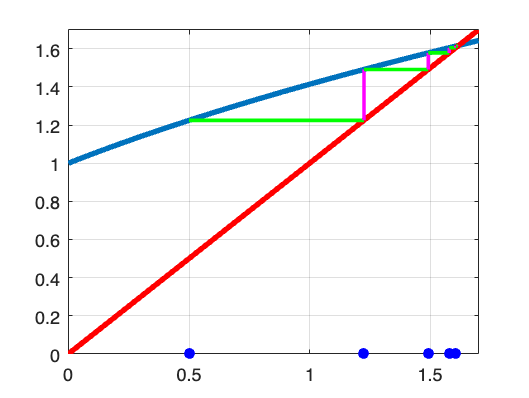

p = y;
hold off

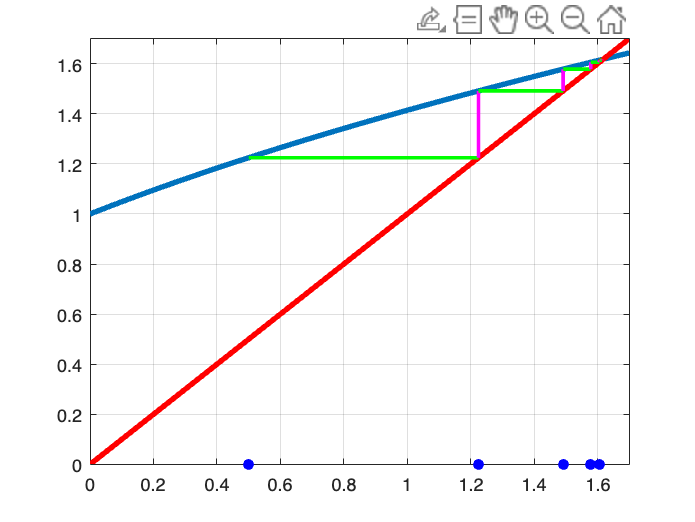

dopo 5 iterazioni, approssimazione =` 1.61686`

Ne calcoliamo la derivata:

g_primo = @(x) 1./(2 * sqrt(x + 1));
g_primo(p)

ans =    0.309086292532575


g_primo =` 0.309086292532575`

Si può notare come g_primo è minore di 1, quindi il metodo converge.

Si ottiene, inoltre, convergenza lineare poiché $g^{\prime } \left(x\right)\not= 0$, quindi:

fprintf("abs(g(p) - p) = %d", abs(g(p) - p))

abs(g(p) - p) = 8.110435e-04

abs(g(p) - p) =` 8.110435e-04`

Si consideri ora il problema $2\left(2-e^{-x} \right)=x$:

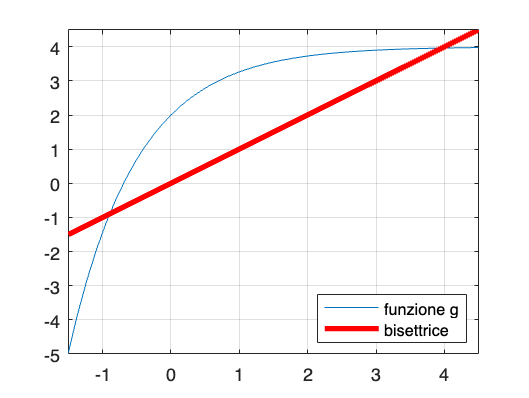

g_1 = @(x) 2*(2-exp(-x));
figure(2)
fplot(g_1, [-1.5, 4.5])
hold on
plot([-1.5 4.5],[-1.5 4.5],'r','linewidth',3)
legend('funzione g', 'bisettrice', 'location', 'southeast')
grid on
hold off